# Meta 3

## 16. Carrega a estrutura de dados guardada na última meta (Meta 2)

load('AED1.mat', 'tabela');  % variável 'tabela' contém os campos gerados nas Metas 1 e 2


## 17. Seleção das melhores características extraídas dos sinais nos domínios do tempo e frequência

% Considerando as análises dos pontos 8 (tempo) e 14 (frequência) escolhemos:
%  - Tempo: EnergiaTotal, FatorCrest, TaxaCruzamento
%  - Frequência: CentroideEspectral, FreqBordaEspectral, LarguraBandaEspectral
features = {'EnergiaTotal','FatorCrest','TaxaCruzamento', ...
            'CentroideEspectral','FreqBordaEspectral','LarguraBandaEspectral'};

% Cria a matriz de características (cada linha corresponde a um sinal)
nAmostras = height(tabela);
X = zeros(nAmostras, numel(features));
for i = 1:numel(features)
    X(:, i) = tabela.(features{i});
end

% Rótulos reais (dígitos) presentes na tabela
y = tabela.Digito;

%% Implementação do Classificador de Distância Mínima com validação Leave-One-Out
% Para cada amostra, calcula-se a distância (norma Euclidiana) entre o seu vetor
% de características e os centroides (médias) dos sinais pertencentes a cada dígito (classe),
% considerando todas as outras amostras.
predicted = zeros(nAmostras,1);  % vetor que armazena a classificação para cada amostra

for i = 1:nAmostras
    % Separação em dados de treino e teste (deixando de fora a amostra i)
    X_test = X(i, :);
    y_test = y(i);  %#ok<NASGU>
    
    % Dados de treino: todas as amostras exceto a i-ésima
    X_train = X;
    y_train = y;
    X_train(i,:) = [];
    y_train(i) = [];
    
    % Obtém as classes (dígitos) presentes nos dados de treino
    classes = unique(y_train);
    distances = zeros(length(classes),1);
    
    % Para cada classe, calcula o centroide (média das features)
    for j = 1:length(classes)
        classe = classes(j);
        idx = (y_train == classe);
        centroide = mean(X_train(idx, :), 1);
        % Calcula a distância entre a amostra de teste e o centroide da classe j
        distances(j) = norm(X_test - centroide);
    end
    
    % Atribui à amostra a classe cujo centroide estiver mais próximo
    [~, minIdx] = min(distances);
    predicted(i) = classes(minIdx);
end

%% Armazena o resultado da classificação na estrutura de dados e salva
tabela.Classificacao = predicted;

disp(tabela);

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento    CoeficientesFourier    AmpEspectralMaxima    FreqAmpMaxima    CentroideEspectral    FreqBordaEspectral    LarguraBandaEspectral    Classificacao
    _______________________________________________________    _______________    ______    ____________

## Exercício 18: Comparação da Classificação e Cálculo da Percentagem de Acertos

% Considerando que o vetor 'predicted' e os rótulos reais 'tabela.Digito' já
% foram calculados no exercício anterior

% Vetor de rótulos reais
y_real = tabela.Digito;

% Calcula quantos dígitos foram classificados corretamente
numAcertos = sum(predicted == y_real);

% Calcula a percentagem de acertos
percentAcertos = (numAcertos / nAmostras) * 100;

% Exibe o resultado
fprintf('Número de dígitos classificados corretamente: %d de %d\n', numAcertos, nAmostras);

Número de dígitos classificados corretamente: 238 de 500


fprintf('Percentagem de acertos: %.2f%%\n', percentAcertos);

Percentagem de acertos: 47.60%



%% Comentário sobre os resultados:
%
% O desempenho do classificador pode ser avaliado pela percentagem de acertos.
% Por exemplo, se a percentagem de acertos for elevada (por exemplo, acima de 80%),
% isso sugere que as características extraídas (no domínio do tempo e frequência) são
% adequadas para discriminar os dígitos e o classificador de distância mínima consegue 
% identificar os dígitos com boa precisão.
%
% Caso a percentagem de acertos seja baixa, podem ser necessárias melhorias como:
% - Revisão na seleção das features (talvez incluir outras características relevantes);
% - Experimentar outros classificadores (por exemplo, classificadores baseados em aprendizado de máquina);
% - Realizar um pré-processamento adicional dos sinais.
%
% Esses insights ajudam a guiar os próximos passos do projeto para otimizar a classificação.


## Exercício 19: Comparação de Três Tipos de Janelas e seus Efeitos

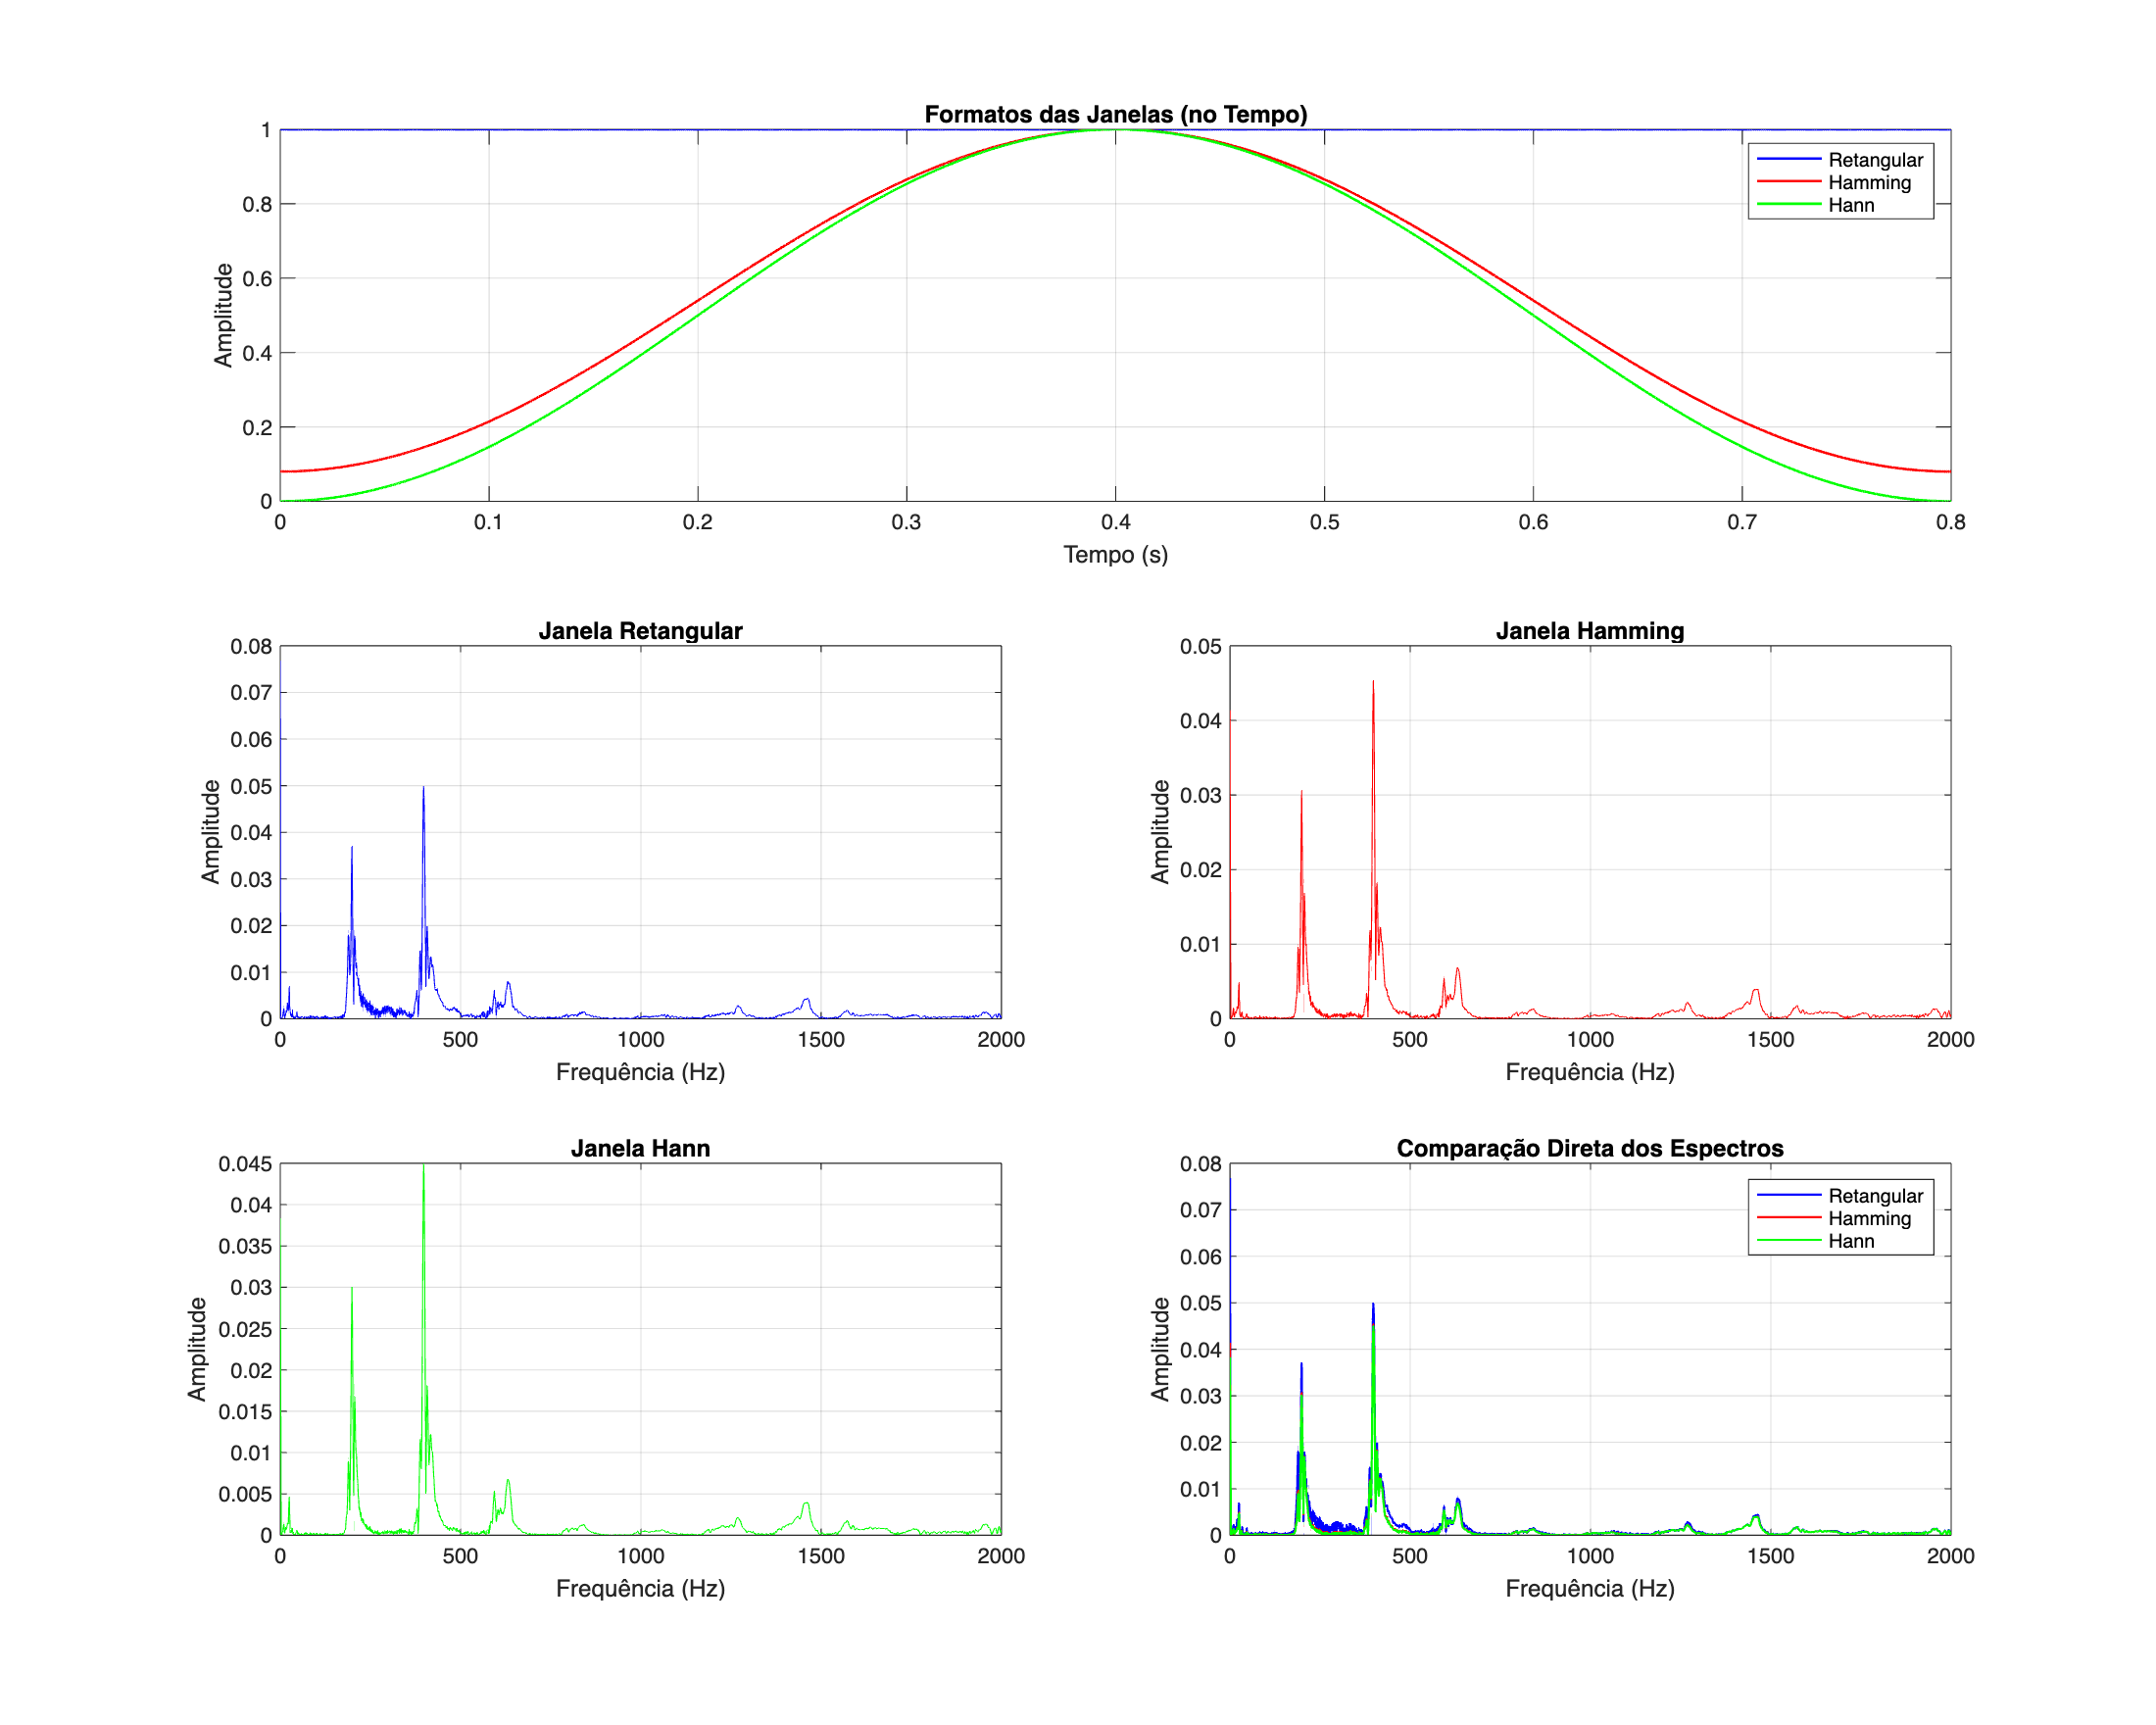

%% Exercício 19: Comparação de Três Tipos de Janelas e seus Efeitos

% Seleciona um exemplo de sinal processado da tabela (por exemplo, o primeiro)
s = tabela.Sinal_Processado{1};  
fs = tabela.Taxa_Amostragem(1);
N = length(s);
t = (0:N-1)/fs;

% Definir três janelas de mesmo tamanho
w_rect = ones(N,1);      % Janela Retangular (equivalente a não aplicar janela)
w_hamming = hamming(N);  % Janela Hamming
w_hann = hann(N);        % Janela Hann

% Aplica as janelas ao sinal (multiplicação ponto a ponto)
s_rect = s .* w_rect;
s_hamming = s .* w_hamming;
s_hann = s .* w_hann;

% Realiza a FFT para cada sinal janela e normaliza pelo número de amostras
S_rect = fft(s_rect) / N;
S_hamming = fft(s_hamming) / N;
S_hann = fft(s_hann) / N;

% Seleciona apenas as frequências positivas
nFreq = floor(N/2) + 1;
freq = (0:nFreq-1) * fs/N;

amp_rect = abs(S_rect(1:nFreq));
amp_hamming = abs(S_hamming(1:nFreq));
amp_hann = abs(S_hann(1:nFreq));

% Índices até 2000 Hz
idx2000 = freq <= 2000;
freq2000 = freq(idx2000);

amp_rect = amp_rect(idx2000);
amp_hamming = amp_hamming(idx2000);
amp_hann = amp_hann(idx2000);

%% Plotagem com frequência máxima de 2000 Hz

figure('Name','Comparação de Janelas e seus Efeitos no Espectro','NumberTitle','off', 'Position', [100, 100, 1000, 800]);

% Subplot 1: Formato das janelas
subplot(3,2,[1 2]);
plot(t, w_rect, 'b', 'LineWidth', 1.2); hold on;
plot(t, w_hamming, 'r', 'LineWidth', 1.2);
plot(t, w_hann, 'g', 'LineWidth', 1.2);
title('Formatos das Janelas (no Tempo)');
xlabel('Tempo (s)');
ylabel('Amplitude');
legend('Retangular', 'Hamming', 'Hann');
grid on;

% Subplot 2: Espectro com janela Retangular
subplot(3,2,3);
plot(freq2000, amp_rect, 'b');
title('Janela Retangular');
xlabel('Frequência (Hz)');
ylabel('Amplitude');
xlim([0 2000]);
grid on;

% Subplot 3: Espectro com janela Hamming
subplot(3,2,4);
plot(freq2000, amp_hamming, 'r');
title('Janela Hamming');
xlabel('Frequência (Hz)');
ylabel('Amplitude');
xlim([0 2000]);
grid on;

% Subplot 4: Espectro com janela Hann
subplot(3,2,5);
plot(freq2000, amp_hann, 'g');
title('Janela Hann');
xlabel('Frequência (Hz)');
ylabel('Amplitude');
xlim([0 2000]);
grid on;

% Subplot 5: Comparação direta entre espectros
subplot(3,2,6);
plot(freq2000, amp_rect, 'b', 'LineWidth', 1); hold on;
plot(freq2000, amp_hamming, 'r', 'LineWidth', 1);
plot(freq2000, amp_hann, 'g', 'LineWidth', 1);
title('Comparação Direta dos Espectros');
xlabel('Frequência (Hz)');
ylabel('Amplitude');
legend('Retangular', 'Hamming', 'Hann');
xlim([0 2000]);
grid on;

%% Comentários sobre os Resultados:
%
% 1. Janela Retangular:
%    - Não realiza suavização nas bordas do sinal, o que pode causar um "leakage" espectral 
%      (distribuição da energia em frequências adjacentes).
%    - Apresenta picos mais altos, mas com lobos laterais maiores, dificultando a distinção de
%      frequências próximas.
%
% 2. Janela Hamming:
%    - Suaviza as bordas do sinal, reduzindo significativamente os lobos laterais.
%    - Resulta em um pico principal mais "limpo", embora a amplitude absoluta possa ser ligeiramente
%      menor devido à atenuação nas bordas.
%
% 3. Janela Hann:
%    - Assim como a janela Hamming, aplica suavização, mas com uma forma de atenuação um pouco diferente.
%    - Pode apresentar uma resolução espectral intermediária, com lobos laterais menores que a janela retangular
%      e um pico principal bem definido.
%
% Em geral, o uso de janelas como Hamming e Hann auxilia na redução do leakage espectral, melhorando a
% estimativa das frequências dominantes. Entretanto, há um trade-off: janelas com maior atenuação nas
% bordas podem reduzir a resolução espectral de picos muito próximos.
%
% A escolha da janela ideal depende da aplicação: se a prioridade for detectar picos de forma precisa, 
% pode ser necessário experimentar diferentes janelas, ajustando o comprimento e o tipo para encontrar o 
% melhor compromisso entre redução de leakage e resolução espectral.

